# MPC Distrubance Rejection

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;
inputGain = 2*kt/(R*r);

%% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)];

## LQR

lqr_weight = [100 1 1e6 1e2];
Q_lqr = diag(lqr_weight);
R_lqr = 1;
C= [1 0 0 0];
D = 0;
K=lqr(A,B,Q_lqr,R_lqr);

## Closed Loop System

A_cl=A-B*K;
B_cl=B;
plant=ss(A_cl,B_cl,C,D);
PP = c2d(plant,0.2,'zoh');
Ad=PP.A;
Bd=PP.B;
Cd=PP.C;
state_n = size(A, 1);

A_new = Ad;%[A zeros(state_n,1); C 1];
B_new = Bd;%[B; 0];
C_new = Cd;%[C 0; zeros(1,state_n) 1];
W_new = [zeros(state_n, 1); -1];

## MPC Formulation

N = 2;
R = 0.1; % Control penalty
Q = 200000;  % output = [position]

Qbar = blkdiag(Q,Q);
Rbar = blkdiag(R,R);

Tbar = [C_new*A_new;C_new*A_new^2];
Sbar = [C_new*B_new zeros(1,1);C_new*A_new*B_new C_new*B_new];
H = 2*(Rbar+Sbar'*Qbar*Sbar);
G = [eye(2);-eye(2)];
S = zeros(2*N,4);
W = 12*ones(2*N,1);

iter = 2000;

Xact = [];
Uopt = [];
X = [0;0;0;0];
U = 0;

U_disturb = 0;
X_disturb = [0; 0; 0; 0];

r = 0.50*ones(iter,1);
% r = square([1:iter+N+1]/200);
warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';

% Simulation
for ii = 1:iter-1
    Xact(:,ii) = X;
    Rbar_ref = [r(ii);r(ii)];
    
    f = 2*(X'*Tbar'*Qbar*Sbar - Rbar_ref'*Qbar*Sbar); 
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    
    Uopt(ii) = Z(1) + U_disturb;
    U = Uopt(ii);

    X = A_new*X + B_new*U + X_disturb;
end

## Plotting

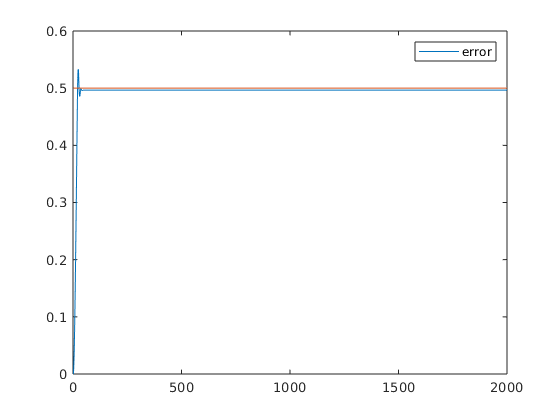

Xact(:,ii+1) = X;

%% Plotting
y=C_new*Xact;
plot([1:iter],y(1,1:iter),[1:iter],r(1:iter))
legend('y','r')
legend('error')

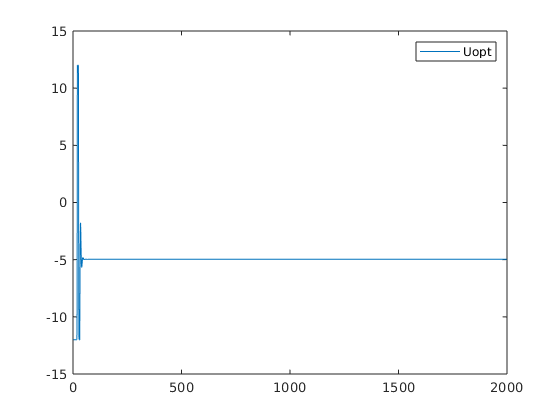

plot([1:iter-1], Uopt(1, 1:iter-1))
legend('Uopt')